%% Quantum Steering Majorization Bound and State Optimization Visualization Script
% 本脚本用于计算并可视化量子导引（Quantum Steering）的 Majorization Bound 以及特定量子态的违背情况。
%
% 主要步骤：
% 1. 设置测量基 (MUBs) 并进行酉变换 (Rotation)。
% 2. 计算变换后测量基的 Majorization Bound (omegak)。
% 3. 使用交叉熵方法 (Cross-Entropy Method) 针对 4 个不同的量子态优化其在测量基下的概率分布。
% 4. 引入白噪声 (Werner state 模型) 并计算混合态的累积概率分布。
% 5. 绘制 Majorization 曲线图，阴影区域表示违背 Steering 界限的区域。


%% 1. 测量基设置与 Majorization Bound 计算

% --- 1.1 初始化测量基 ---
% 假设 mub3 是预先定义好的 3维 MUBs (d=3, 4组基)
% 这里的 mub3 是一个 3x3x4 的数组
% 如果当前工作区没有 mub3，请确保加载或定义它
if ~exist('mub3', 'var')
    % 这里提供一个简单的占位符或报错提示，实际运行时需确保数据存在
    % load('mub3_data.mat'); % 示例
    error('变量 mub3 未定义。请先加载或生成 3维 MUBs 数据。');
end
base_array = mub3;
[d, ~, num] = size(base_array); % d=3, num=4 (通常)

% --- 1.2 酉变换 (Unitary Rotation) ---
% 对无偏基进行沿 z 方向的转动变换
% 定义 SU(2) 生成元 (虽然是在 d=3 空间中操作，这里使用的是子空间嵌入的定义)
J_x = [[0, 0, 0]; [0, 0, -1i]; [0, 1i, 0]];
J_y = [[0, 0, 1i]; [0, 0, 0]; [-1i, 0, 0]];
J_z = [[0, -1i, 0]; [1i, 0, 0]; [0, 0, 0]];

% 转动参数
delta_x = 0;
delta_y = 0;
delta_z = pi/3;

% 复制原始基
mub3_delta = mub3;

% 对第 3 和第 4 组基进行酉变换
% expm 计算矩阵指数
U_rot = expm(-1i*(delta_x*J_x + delta_y*J_y + delta_z*J_z));
% pagemtimes 用于高效的页矩阵乘法 (MATLAB R2020b+), 相当于对每页做 U' * Base
mub3_delta(:,:,3:4) = pagemtimes(mub3(:,:,3:4), 'none', U_rot, 'transpose');

% --- 1.3 计算 Majorization Bound ---
% 计算测量算符的和的最大特征值 (或相关量)，用于确定 Steering Bound
omegak_bound_mub_delta = ones(1, num*d);

% 注意：omegak_batching_optimized 需要在路径中定义
% 计算每增加一个投影算符带来的增量
for i = 2:num*d
    omegak_bound_mub_delta(i) = omegak_batching_optimized(i, mub3_delta, d) - ...
                                omegak_batching_optimized(i-1, mub3_delta, d);
end

开始计算: n=12, k=2, 总组合数=66
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 1.856224 (平均值 0.928112)
总耗时: 0.33 秒


开始计算: n=12, k=1, 总组合数=12
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 1.000000 (平均值 1.000000)
总耗时: 0.02 秒


开始计算: n=12, k=3, 总组合数=220
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 2.527357 (平均值 0.842452)
总耗时: 0.02 秒


开始计算: n=12, k=2, 总组合数=66
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 1.856224 (平均值 0.928112)
总耗时: 0.01 秒


开始计算: n=12, k=4, 总组合数=495
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.069808 (平均值 0.767452)
总耗时: 0.02 秒


开始计算: n=12, k=3, 总组合数=220
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 2.527357 (平均值 0.842452)
总耗时: 0.01 秒


开始计算: n=12, k=5, 总组合数=792
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.391859 (平均值 0.678372)
总耗时: 0.02 秒


开始计算: n=12, k=4, 总组合数=495
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.069808 (平均值 0.767452)
总耗时: 0.02 秒


开始计算: n=12, k=6, 总组合数=924
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.585558 (平均值 0.597593)
总耗时: 0.02 秒


开始计算: n=12, k=5, 总组合数=792
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.391859 (平均值 0.678372)
总耗时: 0.02 秒


开始计算: n=12, k=7, 总组合数=792
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.780686 (平均值 0.540098)
总耗时: 0.02 秒


开始计算: n=12, k=6, 总组合数=924
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.585558 (平均值 0.597593)
总耗时: 0.02 秒


开始计算: n=12, k=8, 总组合数=495
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.962876 (平均值 0.495360)
总耗时: 0.02 秒


开始计算: n=12, k=7, 总组合数=792
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.780686 (平均值 0.540098)
总耗时: 0.07 秒


开始计算: n=12, k=9, 总组合数=220
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.444444)
总耗时: 0.01 秒


开始计算: n=12, k=8, 总组合数=495
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 3.962876 (平均值 0.495360)
总耗时: 0.02 秒


开始计算: n=12, k=10, 总组合数=66
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.400000)
总耗时: 0.01 秒


开始计算: n=12, k=9, 总组合数=220
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.444444)
总耗时: 0.01 秒


开始计算: n=12, k=11, 总组合数=12
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.363636)
总耗时: 0.01 秒


开始计算: n=12, k=10, 总组合数=66
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.400000)
总耗时: 0.01 秒


开始计算: n=12, k=12, 总组合数=1
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.333333)
总耗时: 0.01 秒


开始计算: n=12, k=11, 总组合数=12
并行配置: 批次大小=1000, 总批次数=1
计算完成。全局最大值: 4.000000 (平均值 0.363636)
总耗时: 0.01 秒



% 对增量进行降序排列，得到 Majorization 向量
sort_omegak_bound_mub_delta = sort(omegak_bound_mub_delta, 'descend');


%% 2. 交叉熵优化：计算量子态的最优概率分布

% --- 2.1 优化参数设置 ---
max_iter = 50;      % 最大迭代次数
n_samples = 5000;   % 每代样本数
elite_frac = 0.001; % 精英样本比例 (0.1%)
smoothing = 0.8;    % 分布参数平滑系数

% --- 2.2 待优化的量子态参数 (theta, phi) ---
% 定义 4 个目标态
theta_phi = [
    [0, pi/2];                  % State 1
    [pi/4, pi/2];               % State 2
    [pi/3, pi/3];               % State 3
    [pi/4, asin(sqrt(2/3))]     % State 4
];

num_states = length(theta_phi);
optimal_prob = cell(1, num_states); % 存储每个态的最优分布结果

fprintf('开始交叉熵优化...\n');

开始交叉熵优化...


正在优化第 1/4 个态: theta=0.0000, phi=1.5708 ... 

=== 开始熵最小化优化 (CEM算法) ===
维度 d=3 | 样本数 n=5000 | 精英数=5 | 参数维数=10
>> 迭代 1: 新最优 (Anti-Unitary)! 熵=4.69192149
迭代 001/50: 最优=4.691921, 精英均值=4.733701, Std=3.7906, 耗时=12.75s
>> 迭代 2: 新最优 (Anti-Unitary)! 熵=4.67536583
>> 迭代 4: 新最优 (Unitary)! 熵=4.66248488
>> 迭代 5: 新最优 (Anti-Unitary)! 熵=4.65832188
>> 迭代 6: 新最优 (Anti-Unitary)! 熵=4.65759601
>> 迭代 7: 新最优 (Anti-Unitary)! 熵=4.65748708
>> 迭代 8: 新最优 (Anti-Unitary)! 熵=4.65744091
迭代 010/50: 最优=4.657441, 精英均值=4.657452, Std=0.7798, 耗时=0.90s
>> 迭代 11: 新最优 (Anti-Unitary)! 熵=4.65743639
>> 迭代 12: 新最优 (Anti-Unitary)! 熵=4.65743071
>> 迭代 13: 新最优 (Anti-Unitary)! 熵=4.65742897
>> 迭代 14: 新最优 (Anti-Unitary)! 熵=4.65742804
>> 迭代 15: 新最优 (Anti-Unitary)! 熵=4.65742789
>> 迭代 16: 新最优 (Anti-Unitary)! 熵=4.65742773
>> 迭代 17: 新最优 (Anti-Unitary)! 熵=4.65742767
>> 迭代 18: 新最优 (Anti-Unitary)! 熵=4.65742765
>> 迭代 20: 新最优 (Anti-Unitary)! 熵=4.65742763
迭代 020/50: 最优=4.657428, 精英均值=4.657428, Std=0.0543, 耗时=0.86s
>> 迭代 22: 新最优 (Anti-Unitary)! 熵=4.65742763
>> 迭代 23: 新最优 (Anti-Unitary)! 熵=4.657

完成。


正在优化第 2/4 个态: theta=0.7854, phi=1.5708 ... 

=== 开始熵最小化优化 (CEM算法) ===
维度 d=3 | 样本数 n=5000 | 精英数=5 | 参数维数=10
>> 迭代 1: 新最优 (Anti-Unitary)! 熵=3.85477519
迭代 001/50: 最优=3.854775, 精英均值=3.947414, Std=3.8361, 耗时=0.58s
>> 迭代 2: 新最优 (Anti-Unitary)! 熵=3.76415242
>> 迭代 5: 新最优 (Anti-Unitary)! 熵=3.76192512
>> 迭代 6: 新最优 (Anti-Unitary)! 熵=3.66673213
>> 迭代 7: 新最优 (Anti-Unitary)! 熵=3.58559752
>> 迭代 8: 新最优 (Anti-Unitary)! 熵=3.57891325
>> 迭代 9: 新最优 (Anti-Unitary)! 熵=3.57823683
>> 迭代 10: 新最优 (Anti-Unitary)! 熵=3.57760105
迭代 010/50: 最优=3.577601, 精英均值=3.577801, Std=0.2587, 耗时=0.59s
>> 迭代 11: 新最优 (Anti-Unitary)! 熵=3.57753982
>> 迭代 12: 新最优 (Anti-Unitary)! 熵=3.57747491
>> 迭代 13: 新最优 (Anti-Unitary)! 熵=3.57747105
>> 迭代 14: 新最优 (Anti-Unitary)! 熵=3.57746662
>> 迭代 15: 新最优 (Anti-Unitary)! 熵=3.57746471
>> 迭代 16: 新最优 (Anti-Unitary)! 熵=3.57746399
>> 迭代 17: 新最优 (Anti-Unitary)! 熵=3.57746389
>> 迭代 18: 新最优 (Anti-Unitary)! 熵=3.57746386
>> 迭代 19: 新最优 (Anti-Unitary)! 熵=3.57746385
>> 迭代 20: 新最优 (Anti-Unitary)! 熵=3.57746385
迭代 020/50: 最优=3.577464, 精英均值=3.577464, Std=0.0762,

完成。


正在优化第 3/4 个态: theta=1.0472, phi=1.0472 ... 

=== 开始熵最小化优化 (CEM算法) ===
维度 d=3 | 样本数 n=5000 | 精英数=5 | 参数维数=10
>> 迭代 1: 新最优 (Anti-Unitary)! 熵=1.56928854
迭代 001/50: 最优=1.569289, 精英均值=1.889654, Std=4.0410, 耗时=0.59s
>> 迭代 2: 新最优 (Anti-Unitary)! 熵=1.30565786
>> 迭代 4: 新最优 (Anti-Unitary)! 熵=1.16307748
>> 迭代 5: 新最优 (Anti-Unitary)! 熵=1.09162899
>> 迭代 6: 新最优 (Anti-Unitary)! 熵=0.99525735
>> 迭代 7: 新最优 (Anti-Unitary)! 熵=0.98383031
>> 迭代 8: 新最优 (Anti-Unitary)! 熵=0.97493519
>> 迭代 9: 新最优 (Anti-Unitary)! 熵=0.96989502
>> 迭代 10: 新最优 (Anti-Unitary)! 熵=0.96789329
迭代 010/50: 最优=0.967893, 精英均值=0.971043, Std=0.4090, 耗时=0.58s
>> 迭代 11: 新最优 (Anti-Unitary)! 熵=0.96676274
>> 迭代 14: 新最优 (Anti-Unitary)! 熵=0.96671654
>> 迭代 16: 新最优 (Anti-Unitary)! 熵=0.96664231
>> 迭代 17: 新最优 (Anti-Unitary)! 熵=0.96661797
>> 迭代 19: 新最优 (Anti-Unitary)! 熵=0.96661613
迭代 020/50: 最优=0.966616, 精英均值=0.966619, Std=0.0579, 耗时=0.57s
>> 迭代 21: 新最优 (Anti-Unitary)! 熵=0.96661429
>> 迭代 22: 新最优 (Anti-Unitary)! 熵=0.96661370
>> 迭代 24: 新最优 (Anti-Unitary)! 熵=0.96661354
>> 迭代 25: 新最优 (Anti-Unitary)! 熵=0.

完成。


正在优化第 4/4 个态: theta=0.7854, phi=0.9553 ... 

=== 开始熵最小化优化 (CEM算法) ===
维度 d=3 | 样本数 n=5000 | 精英数=5 | 参数维数=10
>> 迭代 1: 新最优 (Anti-Unitary)! 熵=0.82134690
迭代 001/50: 最优=0.821347, 精英均值=1.518174, Std=3.3568, 耗时=0.59s
>> 迭代 2: 新最优 (Anti-Unitary)! 熵=0.46362487
>> 迭代 3: 新最优 (Anti-Unitary)! 熵=0.27992622
>> 迭代 4: 新最优 (Anti-Unitary)! 熵=0.14909317
>> 迭代 6: 新最优 (Anti-Unitary)! 熵=0.09239522
>> 迭代 7: 新最优 (Anti-Unitary)! 熵=0.05835248
>> 迭代 8: 新最优 (Anti-Unitary)! 熵=0.00605616
>> 迭代 10: 新最优 (Anti-Unitary)! 熵=0.00469798
迭代 010/50: 最优=0.004698, 精英均值=0.007718, Std=0.2981, 耗时=0.59s
>> 迭代 12: 新最优 (Anti-Unitary)! 熵=0.00147585
>> 迭代 13: 新最优 (Anti-Unitary)! 熵=0.00098003
>> 迭代 14: 新最优 (Anti-Unitary)! 熵=0.00033764
>> 迭代 15: 新最优 (Anti-Unitary)! 熵=0.00014568
>> 迭代 16: 新最优 (Anti-Unitary)! 熵=0.00001751
迭代 020/50: 最优=0.000018, 精英均值=0.000068, Std=0.0885, 耗时=0.58s
>> 迭代 22: 新最优 (Anti-Unitary)! 熵=0.00000764
>> 迭代 25: 新最优 (Anti-Unitary)! 熵=0.00000286
>> 迭代 26: 新最优 (Anti-Unitary)! 熵=0.00000118
>> 迭代 27: 新最优 (Anti-Unitary)! 熵=0.00000069
>> 迭代 28: 新最优 (Anti-Unitary)! 熵=0

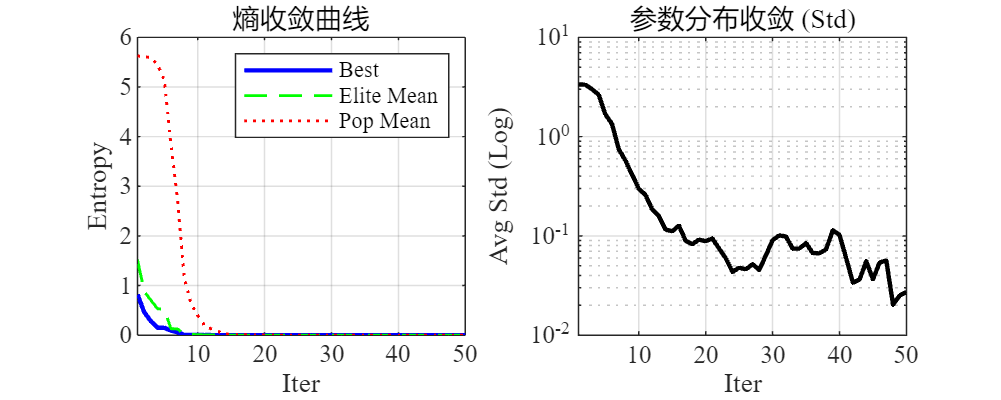

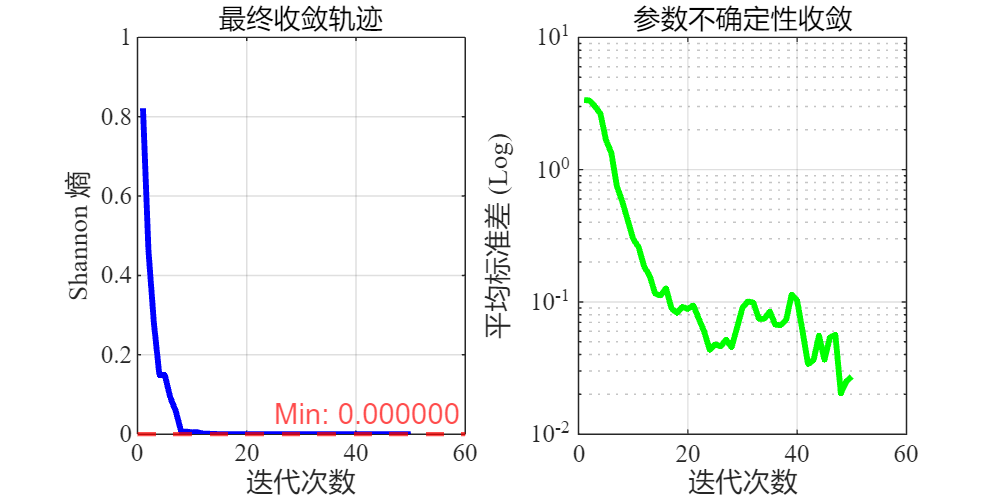

完成。



% --- 2.3 循环优化每个态 ---
for i = 1:num_states
    theta = theta_phi(i, 1);
    phi = theta_phi(i, 2);
    
    fprintf('正在优化第 %d/%d 个态: theta=%.4f, phi=%.4f ... ', i, num_states, theta, phi);
    
    % 构造密度矩阵 rho_psi (纯态)
    % 这里是硬编码的 9x9 矩阵形式，对应 d=3 系统的特定参数化
    % 注意：矩阵仅在特定元素上有非零值
    rhopsi = zeros(9, 9);
    
    % 填充非零元素 (基于给定的公式)
    rhopsi(1,1) = cos(theta)^2*sin(phi)^2;
    rhopsi(1,5) = sin(theta)*cos(theta)*sin(phi)^2;
    rhopsi(1,9) = cos(theta)*sin(phi)*cos(phi);
    
    rhopsi(5,1) = sin(theta)*cos(theta)*sin(phi)^2;
    rhopsi(5,5) = sin(theta)^2*sin(phi)^2;
    rhopsi(5,9) = sin(theta)*sin(phi)*cos(phi);
    
    rhopsi(9,1) = cos(theta)*sin(phi)*cos(phi);
    rhopsi(9,5) = sin(theta)*sin(phi)*cos(phi);
    rhopsi(9,9) = cos(phi)^2;
    
    % 执行交叉熵优化 minimization_entropy
    % 该函数应寻找使熵最小(或特定目标函数最优)的概率分布
    [~, optimal_prob_dist, ~, ~] = minimization_entropy(d, rhopsi, ...
        mub3_delta, max_iter, n_samples, elite_frac, smoothing);
    
    optimal_prob{i} = optimal_prob_dist;
    fprintf('完成。\n');
end

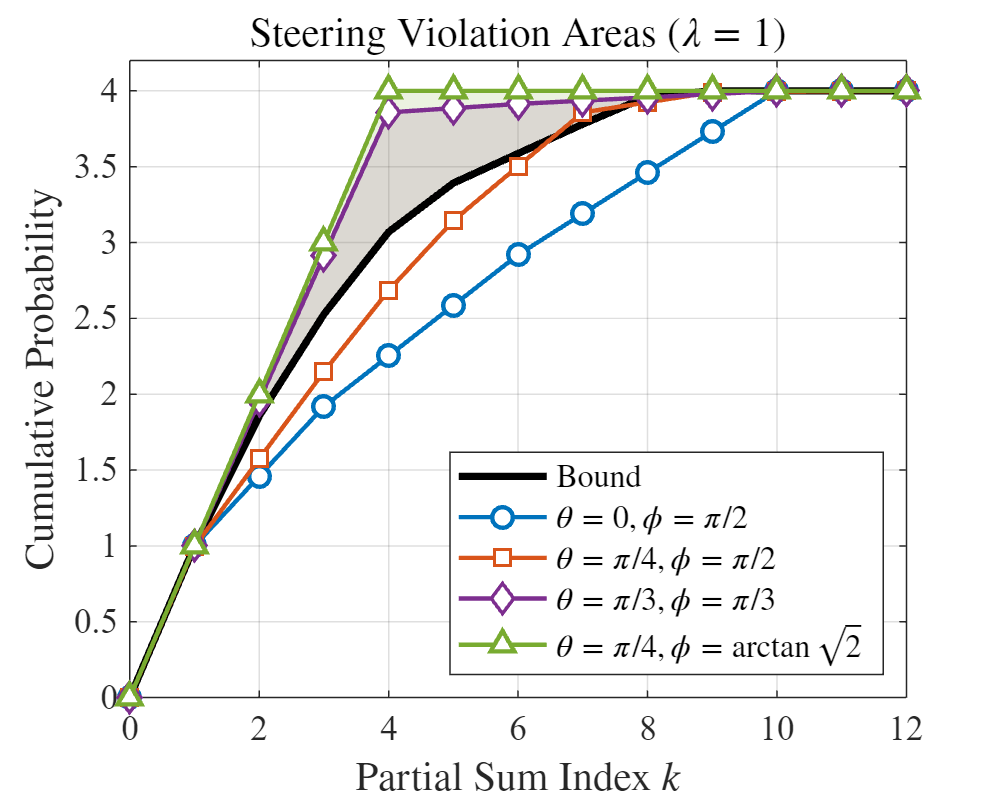



%% 3. 数据处理：引入噪声与排序

% --- 3.1 噪声参数 ---
lambda = 1; % 混合参数 (Visibility), 1 为纯态，0 为完全混合态
% 临界点备注: 0.8 (k=7), 0.4817 (k=4)

% 严格噪声定义 (白噪声分布)
noise_vec = ones(num*d, 1) / (num*d); 
% 保持原代码逻辑不变:
noise_vec = ones(3*4, 1) / 3; 

% --- 3.2 绘图样式配置 ---
legend_labels = {'$\theta = 0, \phi = \pi/2$', ...
                 '$\theta = \pi/4, \phi = \pi/2$', ...
                 '$\theta = \pi/3, \phi = \pi/3$', ...
                 '$\theta = \pi/4, \phi = \arctan\sqrt{2}$'};

colors_list = [0.00, 0.45, 0.74; ... % 蓝
               0.85, 0.33, 0.10; ... % 红
               0.49, 0.18, 0.56; ... % 紫
               0.47, 0.67, 0.19];    % 绿

markers_list = {'o', 's', 'd', '^'}; 
num_curves = length(legend_labels); 

% --- 3.3 计算累积概率分布 ---
% 准备 Bound 数据
if size(sort_omegak_bound_mub_delta, 2) > 1 
    sort_omegak_bound_mub_delta = sort_omegak_bound_mub_delta'; 
end
x_orig = 0:length(sort_omegak_bound_mub_delta);
y_bound_orig = [0; cumsum(sort_omegak_bound_mub_delta)];

y_states_noisy = cell(1, num_curves);

% 检查数据完整性
if length(optimal_prob) < num_curves
    error('请确保 optimal_prob 包含了所有目标态的数据');
end

for j = 1:num_curves
    p_pure = optimal_prob{j};
    if size(p_pure, 2) > 1; p_pure = p_pure'; end
    
    % 1. 混合态公式: p = lambda * p_pure + (1-lambda) * p_noise
    p_mixed = lambda * p_pure + (1 - lambda) * noise_vec;
    
    % 2. 降序排列 (Majorization 要求)
    p_sorted = sort(p_mixed, 'descend');
    
    % 3. 计算累积和
    y_states_noisy{j} = [0; cumsum(p_sorted)];
end


%% 4. 绘图：Majorization 曲线与阴影区域

figure('Color', 'w', 'Position', [200, 200, 750, 600]);
hold on; box on;
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);

% --- A. 绘制精准阴影 (Steering Violation Area) ---
% 阴影逻辑：当态的累积概率 > Bound 的累积概率时，填充该区域
for j = 1:num_curves
    y_curr_orig = y_states_noisy{j};
    
    % 计算差值寻找交叉点
    diff_vals = y_curr_orig - y_bound_orig;
    % 寻找符号改变的位置 (即交叉点区间)
    cross_indices = find((diff_vals(1:end-1) .* diff_vals(2:end)) < 0);
    
    % 线性插值计算精确交叉点的 X 坐标
    x_crossings = [];
    for k = cross_indices'
        % diff(k) + t * (diff(k+1)-diff(k)) = 0  =>  t = -diff(k) / delta
        t = -diff_vals(k) / (diff_vals(k+1) - diff_vals(k));
        x_crossings = [x_crossings, x_orig(k) + t]; %#ok<AGROW>
    end
    
    % 构建增强的坐标轴 (原始点 + 交叉点)
    x_augmented = unique([x_orig, x_crossings]);
    
    % 插值得到增强后的 Y 值
    y_state_aug = interp1(x_orig, y_curr_orig, x_augmented, 'linear');
    y_bound_aug = interp1(x_orig, y_bound_orig, x_augmented, 'linear');
    
    % 提取需要填充的区域 (State > Bound)
    % 使用微小阈值 1e-12 防止浮点误差
    mask = (y_state_aug >= y_bound_aug - 1e-12);
    
    if any(mask)
        x_poly = x_augmented(mask);
        y_upper = y_state_aug(mask);
        y_lower = y_bound_aug(mask);
        
        % fill 函数绘制多边形
        fill([x_poly, fliplr(x_poly)], [y_upper, fliplr(y_lower)], ...
            colors_list(j, :), ...
            'FaceAlpha', 0.15, ...     % 透明度
            'EdgeColor', 'none', ...   % 无边框
            'HandleVisibility', 'off'); % 不在图例中显示
    end
end

% --- B. 绘制 Bound 曲线 (黑色实线) ---
plot(x_orig, y_bound_orig, 'k-', 'LineWidth', 2.5, 'DisplayName', 'Bound');

% --- C. 绘制 4 条量子态曲线 ---
for j = 1:num_curves
    plot(x_orig, y_states_noisy{j}, ...
        'LineStyle', '-', ...
        'LineWidth', 1.5, ...
        'Color', colors_list(j, :), ...
        'Marker', markers_list{j}, ...
        'MarkerSize', 7, ...
        'MarkerFaceColor', 'w', ...
        'DisplayName', legend_labels{j});
end

% --- D. 图表装饰 ---
title(['Steering Violation Areas ($\lambda = ' num2str(lambda) '$)'], ...
    'Interpreter', 'latex', 'FontSize', 14);
xlabel('Partial Sum Index $k$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Cumulative Probability', 'Interpreter', 'latex', 'FontSize', 14);

% 图例设置
lgd = legend('show');
set(lgd, 'Interpreter', 'latex', 'Location', 'southeast', 'FontSize', 11);

grid on; axis tight;

% 自动调整 Y 轴上限，留出 5% 的空白
max_val = max(cellfun(@max, y_states_noisy));
ylim([0, max(max_val, y_bound_orig(end)) * 1.05]);

hold off;